## Initialize the FMCW Radar Computations

clear;
clf;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/BlackBoxRadarAttacks/MATLAB/config_files/";
% file_path = "20MHz_USRP.json";
% file_path = "20MHz_USRP_revA.json";
file_path = "20MHz_USRP_revB.json";
% file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "100MHz_USRP.json";
% file_path = "1GHz.json";
% file_path = "4GHz.json";
simulator.load_params_from_JSON(david_path + file_path);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_usrp_attacker_and_victim_position_and_velocity();

%print out key parameters

simulator.Victim.print_radar_parameters;

Chirp Parameters
	 Start Frequency: 		 3.00 GHz
	 Frequency Slope: 		 0.10 MHz/us
	 Idle Time: 			 11.28 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 7.52 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 0.27 MSps
	 Ramp End Time: 		 248.12 us
	 Chirp Tx Bandwidth: 		 24.99 MHz
	 Chirp Sampling Bandwidth: 	 24.23 MHz
	 ADC Sampling Period: 		 240.60 us
	 Chirp Cycle Time: 		 259.40 us
	 Chirp Wavelength: 		 99.93 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 100.13 ms
	 Active Frame Time 		 66.41 ms
Performance Specifications
	 Max Range 			 395.95 m
	 Range Resolution 		 6.19 m
	 Max Velocity 			 96.31 m/s
	 Velocity Resolution 		 0.75 m/s
FMCW Specifications
	 FMCW sampling rate 		 25.00 MHz
	 Downsampling factor 		 94
	 Sweep time 			 248.12 us
	 Samples per chirp 		 6486.00 
CFAR Detection Region
	 Range Detection Region 		 37.121 m to 352.645 m
	 Velocity Detection Region 		 -85.024 m/s to 85.776 m/s


### Initialize the target

% target_pos = 350;
% target_vel = 10;
% simulator.load_target_realistic(target_pos,target_vel);

### Initialize the Victim and Simulation Parameters

%specify the number of frames and chirps to compute
frames_to_compute = 10;

% %specify whether or not to record a move of the range-doppler plot
% record_movie = true;
% simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute, ...
%     record_movie,target_pos,-1 * target_vel,80);
% 
% %pre-compute the victim's chirps
% simulator.Victim.precompute_radar_chirps();

### Initialize the Attacker

%initialize the attacker parameters
% simulator.Attacker.initialize_attacker(...
%                         simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
%                         simulator.Victim.StartFrequency_GHz,...
%                         simulator.Victim.Chirp_Tx_Bandwidth_MHz);
% 
% %initialize the sensing subsystem's debugger
% simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(0,simulator.Victim,frames_to_compute);
% %set to change 1 to zero to disable
% 
% % attack_type = "velocity spoof - noisy";
% % attack_type = "velocity spoof - similar velocity";
% % attack_type = "range spoof - similar slope";
% % attack_type = "range spoof - similar slope, velocity spoof - noisy";
% % attack_type = "range spoof - similar slope, velocity spoof - similar velocity";
% attack_type = "target";
% %initialize the attacker
% simulator.Attacker.Subsystem_attacking.set_attack_mode(attack_type);
% 
% 
% %if it is desired to specify a specific attack location
% if attack_type == "target"
%     desired_pos = 300;
%     desired_vel = -1000;
%     simulator.Attacker.Subsystem_attacking.set_desired_attack_location(desired_pos,desired_vel);
% end

## Save the victim chirp to a file

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/MATLAB_full_chirps/MATLAB_chirp_full.bin";
simulator.save_to_file(simulator.Victim.chirp,path,'float32');

### Plot Tx Chirp to confirm correctness

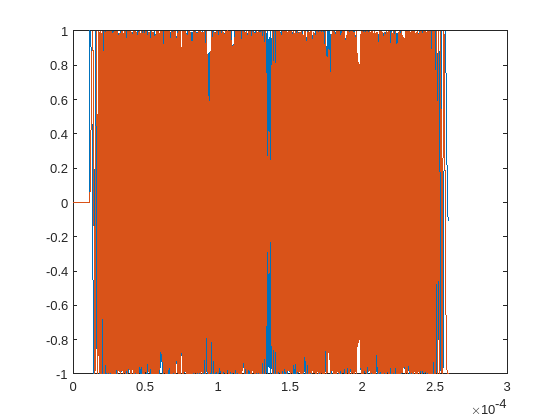

%plot the chirp signal
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
data = simulator.Victim.chirp;
plot(t,real(data),t,imag(data))

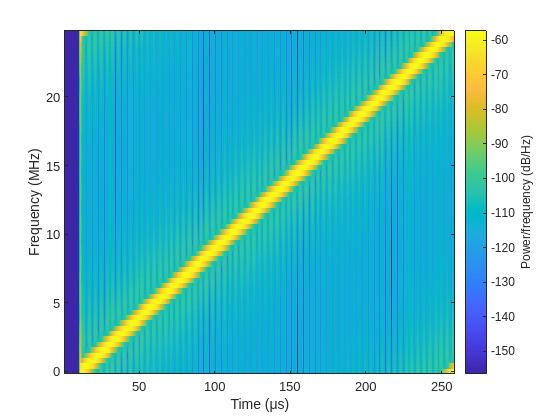

spectrogram(data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## Run simulation if desired to compare results

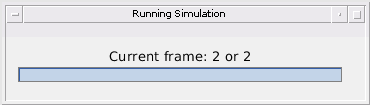

ans = 1

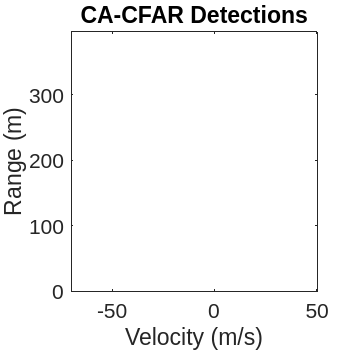

%run the simulation (without an attacker for now)
% frames_to_compute = 2;
% simulator.run_simulation_with_attack(frames_to_compute,true);

## RUN EXPERIMENT ON USRP DEVICE - SENSING ONLY

## [Optional] Get sensing system received signal from USRP device

## Verify C++ computations

### Spectrogram Generation

#### Get key initialization parameters

num_rows = 722;
fft_size = 128;
samples_per_sampling_window = 175;
samp_freq = 25.004 * 1e6;

%load the times/frequencies used for spectrogram generation in the cpp code
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_spectrogram_times.bin";
spectrogram_times = simulator.read_from_file(path,false,"double");

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_spectrogram_frequencies.bin";
spectrogram_frequencies = simulator.read_from_file(path,false,"double");

fprintf(" rows: %d \n samples per sampling window: %d \n fft size: %d \n samp freq: %d",...
    num_rows,samples_per_sampling_window,fft_size,samp_freq);

 rows: 722 
 samples per sampling window: 175 
 fft size: 128 
 samp freq: 25004000

% %print key properties for spectrum subsystem
% num_rows = size(simulator.Attacker.Subsystem_spectrum_sensing.reshaped_signal,2);
% samples_per_sampling_window = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.num_samples_per_sampling_window;
% fft_size = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.fft_size;
% samp_freq = simulator.Attacker.FMCW_sample_rate_Msps * 1e6;
% 
% fprintf(" rows: %d \n samples per sampling window: %d \n fft size: %d \n samp freq: %d",...
%     num_rows,samples_per_sampling_window,fft_size,samp_freq);

#### Verify Hanning Window

%get the hanning window
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_hanning_window.bin";
read_data = simulator.read_from_file(path,true,"float");

%compare with the computed hanning window
compare = all(abs(read_data - hann(fft_size)) < 1e-5);
if compare
    fprintf("Hanning window matches")
else
    fprintf("Hanning window doesn't match")
end

Hanning window matches

#### Reshaped and windowed Received Signal - save received signal to file

% %print the number of received samples
% received_samples = size(simulator.Attacker.Subsystem_spectrum_sensing.received_signal,2);
% fprintf(" receieved_samples: %d\n",received_samples)

#### Reshape Received Signal - read and verify

%get the reshaped for fft signal
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_reshaped_and_windowed_for_fft.bin";

read_data = simulator.read_from_file(path,true,"float");
read_data_reshaped = reshape(read_data,fft_size,num_rows);

#### Generated Spectrogram

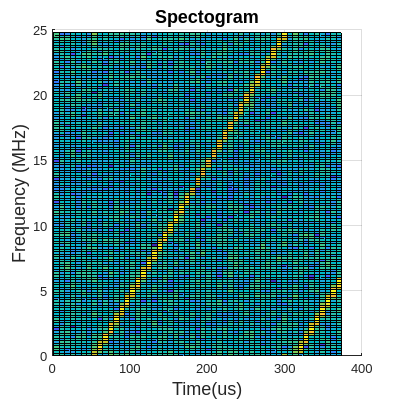

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_generated_spectrogram.bin";

read_data = simulator.read_from_file(path,false,"float");
read_data_reshaped = reshape(read_data,fft_size,num_rows);

max_time_to_plot_us = 200;
idx_to_plot = times < max_time_to_plot_us;

clf;
set(gcf,'Position',[100 100 400 400])
font_size = 14;
ax = gca;
ax.FontSize = font_size;
surf(spectrogram_times(idx_to_plot),...
    spectrogram_frequencies,...
    read_data_reshaped(:,idx_to_plot));
title_str = sprintf('Spectogram');
title(title_str,"FontSize",font_size);
xlabel('Time(us)',"FontSize",font_size)
ylabel('Frequency (MHz)',"FontSize",font_size)
view([0,90.0])

#### Detected Times and Frequencies - read and verify

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_frequencies.bin";

read_data_detected_frequencies = simulator.read_from_file(path,false,"double");

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_times.bin";
read_data_detected_times = simulator.read_from_file(path,false,"double");

#### Clusters - read and verify

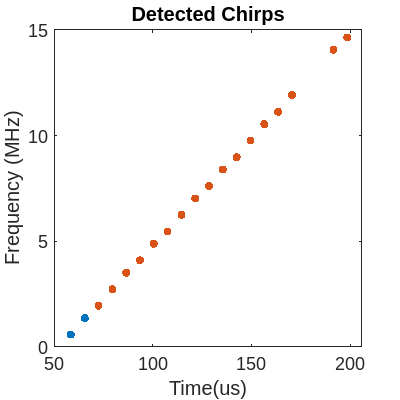

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_computed_clusters.bin";
read_data = simulator.read_from_file(path,false,"int");
read_data_idx = read_data(read_data ~= 0);

idx_to_plot = read_data_detected_times < max_time_to_plot_us;

clf;

gscatter(read_data_detected_times(idx_to_plot), ...
    read_data_detected_frequencies(idx_to_plot), ...
    read_data_idx(idx_to_plot));
set(gcf,'Position',[100 100 400 400])
font_size = 14;
title_str = sprintf('Detected Chirps');
title(title_str,"FontSize",font_size);
xlabel('Time(us)',"FontSize",font_size)
ylabel('Frequency (MHz)',"FontSize",font_size)
ax = gca;
ax.FontSize = font_size;
legend off;

#### Computed Linear Models

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_slopes.bin";
read_data_detected_slopes = simulator.read_from_file(path,false,"double")

read_data_detected_slopes =     0.1008
    0.1008
    0.1006
    0.1007
    0.1006
    0.1006
    0.1008
    0.1007
    0.1005
    0.1007




path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_intercepts.bin";
read_data_intercepts = simulator.read_from_file(path,false,"double")

read_data_intercepts = 1.0e+06 *

    3.1501
    3.1503
    3.1506
    3.1509
    3.1511
    3.1514
    3.1516
    3.1519
    3.1522
    3.1524


%captured chirps buffer
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_chirp_estimates.bin";
captured_chirps_buffer = simulator.read_from_file(path,false,"double")

captured_chirps_buffer =   258.9851
  259.0665
  259.1313
  259.1313
  259.1313
  259.1313
  259.1313
  259.1313
  259.1313
  259.1313


#### Captured Frames Array

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_captured_frames.bin";
read_data = simulator.read_from_file(path,false,"double");
captured_frames = reshape(read_data,6,[]).'

captured_frames = 1.0e+06 *

         0         0         0         0    0.2501         0
         0         0         0         0    0.3501    0.4503
         0         0         0         0    0.4501    0.5503
         0         0         0         0    0.5501    0.6503
         0         0         0         0    0.6501    0.7503
         0         0         0         0    0.7501    0.8503
         0         0         0         0    0.8501    0.9503
         0         0         0         0    0.9501    1.0503
         0         0         0         0    1.0501    1.1503
         0         0         0         0    1.1501    1.2503


estimation_errors_ns = (captured_frames(2:end - 1,6) - captured_frames(3:end,5) ...
    - simulator.Victim.ChirpCycleTime_us) * 1e3

estimation_errors_ns =   302.7766
   41.0128
  204.4457
  -47.9057
    6.5300
  -32.4141
   16.9537
   16.4493
  -23.9424
   19.7445


average_error_ns = mean(estimation_errors_ns(3:end))

average_error_ns = 15.1416

error_stdev_ns_squared = sqrt(var(estimation_errors_ns(3:end)))

error_stdev_ns_squared = 44.7973

### Get the estimated parameters

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_estimated_parameters.bin";
read_data = simulator.read_from_file(path,false,"double");
estimated_frame_duration_ms = read_data(1);
estimated_chirp_duration_us = read_data(2);
estimated_chirp_slope_MHz_us = read_data(3);

% %print out the relevant information
fprintf("Average Frame Duration: %3.7f ms",estimated_frame_duration_ms);

Average Frame Duration: 99.9998500 ms

fprintf("Average Chirp Duration: %3.3f us",estimated_chirp_duration_us);

Average Chirp Duration: 259.414 us

fprintf("Average Slope: %1.3f MHz/us",estimated_chirp_slope_MHz_us);

Average Slope: 0.101 MHz/us

### Estimation Errors

% %print out the relevant information
actual_frame_duration_ms = 100;
fprintf("Frame Duration Error: %3.5f ns",(estimated_frame_duration_ms - actual_frame_duration_ms) * 1e6);

Frame Duration Error: -149.96433 ns

fprintf("Chirp Duration Error: %3.5f ns",(estimated_chirp_duration_us - simulator.Victim.ChirpCycleTime_us) * 1e3);

Chirp Duration Error: 15.09717 ns

fprintf("Slope Error: %1.5f MHz/us",estimated_chirp_slope_MHz_us - simulator.Victim.FrequencySlope_MHz_us);

Slope Error: -0.00006 MHz/us

### Computed Victim Waveform from Attacker

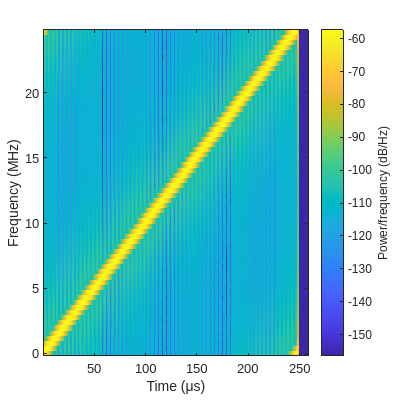

clf;
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_computed_victim_waveform.bin";
estimated_waveform = simulator.read_from_file(path,true,"float32");
spectrogram(estimated_waveform,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

### Computed Cross-Correlation

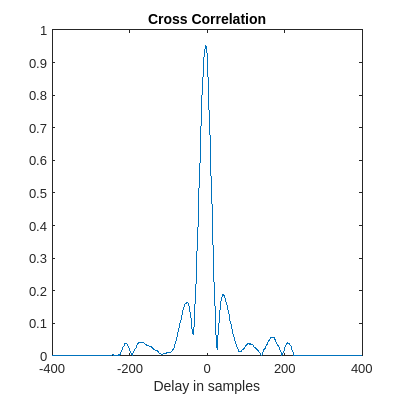

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cross_correlation_result.bin";
result = simulator.read_from_file(path,true,"float32");

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cross_correlation_lags.bin";
lags = simulator.read_from_file(path,false,"int");

%plot the computed cross correlation
clf;
plot(lags,abs(result));
xlabel("Delay in samples")
title("Cross Correlation")

### Reset simulation and compute attack chirp

%reset locations
simulator.load_usrp_attacker_and_victim_position_and_velocity();
simulator.load_target_realistic(target_pos,target_vel);

current_frame = 1;
num_samples_sent = 1;
[victim_pos, victim_vel,attacker_pos, attacker_vel, tgt_pos,tgt_vel] = ...
                    simulator.FMCW_determine_positions_and_velocities(...
                    current_frame,num_samples_sent);
simulator.Attacker.update_victim_pos_and_velocity(attacker_pos,victim_pos,attacker_vel, victim_vel);
simulator.Attacker.update_target_pos_and_velocity(victim_pos, tgt_pos, victim_vel,tgt_vel);
simulator.Attacker.Subsystem_attacking.frame = 1;

%send configuration to the attacker

simulator.Attacker.Subsystem_attacking.compute_calculated_values( ...
    estimated_chirp_duration_us, ...
    estimated_chirp_slope_MHz_us, ...
    estimated_frame_duration_ms, ...
    256);

simulator.Attacker.Subsystem_attacking.compute_next_emulated_chirps();

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/MATLAB_attacking_chirps_full.bin";

%get the eumulated chirps
write_data = simulator.Attacker.Subsystem_attacking.emulated_chirps;

%reshape to be able to send to a file
write_data = reshape(write_data,[],1);
simulator.save_to_file(write_data,path,"double");

attack_chirp = simulator.Attacker.Subsystem_attacking.emulated_chirps(:,1);
spectrogram(attack_chirp,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## RUN ATTACK ON MATLAB

### Read Rx data from MATLAB

path = "/home/david/Documents/MATLAB_generated/cpp_rx_data_files/cpp_rx_data.bin";
read_data = simulator.read_from_file(path,true,"float");

num_chirps = simulator.Victim.NumChirps;
samples_per_chirp = simulator.Victim.ChirpCycleTime_us * 1e-6 * simulator.Victim.FMCW_sampling_rate_Hz;
read_data = reshape(read_data,int32(samples_per_chirp),num_chirps,[]);

%determine the number of frames recorded
num_frames = size(read_data,3);

### Plot Rx Chirp to confirm correctness

Specify chirp:

chirp =128;

Specify frame:

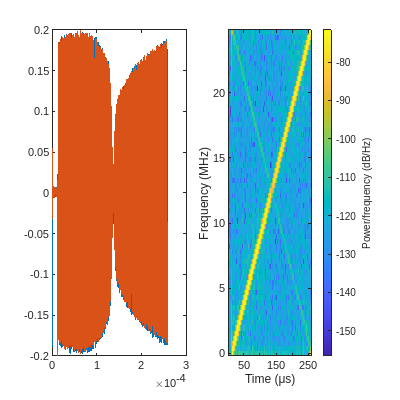

frame = 27;
first_frame = read_data(:,:,1);
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
clf;
subplot(1,2,1);
plot(t,real(read_data(:,chirp,frame)),t,imag(read_data(:,chirp,frame)))
subplot(1,2,2)
spectrogram(read_data(:,chirp,frame),64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

### Initialize the Victim and Simulation Parameters

%specify the number of frames and chirps to compute
clf;
% frames_to_compute = size(read_data,3);
chirps_to_compute = simulator.Victim.NumChirps;
frames_to_compute = 30;

%reset the movie and range estimates
simulator.Victim.Radar_Signal_Processor.F_rngdop = struct('cdata',[],'colormap',[]);
simulator.Victim.Radar_Signal_Processor.F_clusters = struct('cdata',[],'colormap',[]);
simulator.Victim.Radar_Signal_Processor.range_estimates = [];
simulator.Victim.Radar_Signal_Processor.velocity_estimates = [];

%specify whether or not to record a move of the range-doppler plot
record_movie = true;
simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute, ...
    record_movie,target_pos,-1 * target_vel,80);

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

### Process Received Rx Signal

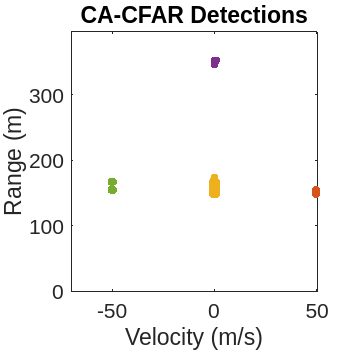



%get the radar chirp generator and the target emulator ready
simulator.Victim.precompute_radar_chirps();

for frame = int32(1:frames_to_compute)
    
    %initialize a clean radar cube
    simulator.Victim.Radar_Signal_Processor.reset_radar_cube();
    simulator.Victim.current_frame = frame;
    
    for chirp = int32(1:chirps_to_compute)
    
        %get the Tx chirp and the chirp received from the emulator
        Rx_sig = read_data(:,chirp,frame);
        Tx_sig = simulator.Victim.chirps(:,chirp);      
                
        %assemble the radar cube
        simulator.Victim.Radar_Signal_Processor.update_radar_cube(Tx_sig,Rx_sig,chirp);
    end

    simulator.Victim.Radar_Signal_Processor.process_radar_cube();
end

## Results

%get the estimated ranges and velocities
simulator.Victim.Radar_Signal_Processor.range_estimates

ans =   155.1645  154.7006  351.4621  271.7656       NaN
  163.4832  155.0062  154.7037  351.8677  155.9684
  351.7107  154.5354  154.7061  155.4530  271.9035
  295.2777  153.3342  154.7074  351.8084  155.4906
   37.2963  154.0981  154.7149  351.8748  154.6921
  156.2128  153.5823  154.7307  351.8220  271.7710
  149.6413  153.3682  154.7375  351.5797  155.4781
  294.9706  154.0311  154.7402  155.0038  271.8809
  351.5747  154.8589  154.7404  155.4507  272.0465
  295.0461  154.7403  351.7159  272.1455       NaN


simulator.Victim.Radar_Signal_Processor.velocity_estimates

ans =   -25.0391   -0.0003   -0.0094  -75.3716       NaN
   85.2357   49.9106   -0.0004   -0.0119  -49.9076
   -0.0087   50.0691    0.0002  -49.9275  -75.3853
   -0.0019   49.9327   -0.0005   -0.0050  -49.8393
   75.3213   49.9162   -0.0004   -0.0026  -49.9315
  -49.9707   49.9502    0.0004    0.0046  -75.3769
  -42.7031   50.0375    0.0002    0.0042  -49.9694
   -0.0078   49.9624    0.0003  -49.8762  -75.3850
    0.0018   50.0204   -0.0001  -50.0216  -75.3727
    0.0016   -0.0001   -0.0108  -75.3895       NaN


%play the movie for the range doppler
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_range_doppler_movie();
end

%play the movie for the clusters
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_clustering_movie()
end

#### Generating Clustering and Range-Doppler Response Figures

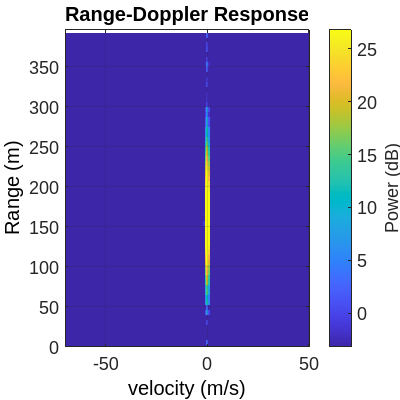

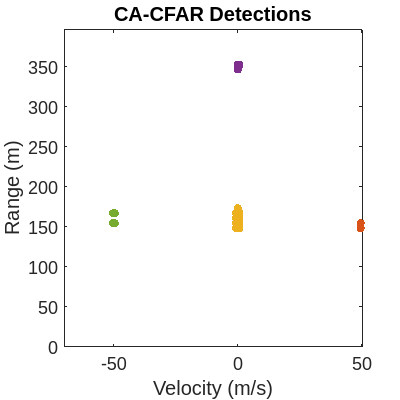

%range-doppler response
clf;
[resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(...
    simulator.Victim.Radar_Signal_Processor.radar_cube);
resp_max = 10*log10(abs(max(resp,[],"all")));

%CA CFAR 2-D
detections = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(...
    abs(resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);
detected_velocities = dopgrid(detections(2,:));
detected_ranges = rnggrid(detections(1,:));



%estimate the range and the velocities
if ~isempty(detections)

    %DBSCAN Clustering
    idx = dbscan(detections.',...
        simulator.Victim.Radar_Signal_Processor.Epsilon,...
        simulator.Victim.Radar_Signal_Processor.minpts);

    %plot the range-doppler and clustering responses
    
    %plot range doppler
    plotResponse( ...
        simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse, ...
        simulator.Victim.Radar_Signal_Processor.radar_cube);
    
    %zoom the range doppler plot
    tgt_velocity = simulator.Victim.Radar_Signal_Processor.tgt_velocity;
    tgt_range = simulator.Victim.Radar_Signal_Processor.tgt_range;
    num_bins_zoom = simulator.Victim.Radar_Signal_Processor.num_bins_zoom;

    clim([resp_max-30, resp_max]);
    xlim([max(tgt_velocity - num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        -1 * simulator.Victim.V_Max_m_per_s), ...
        min(tgt_velocity + num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        simulator.Victim.V_Max_m_per_s)])
    ylim([max(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3)...
        - num_bins_zoom * simulator.Victim.Range_Res_m,...
        0), ...
        min(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3 ...
        * tgt_velocity) ...
        + num_bins_zoom * simulator.Victim.Range_Res_m,...
        simulator.Victim.Range_Max_m)])
    
    font_size = 14;
    h = colorbar;
    h.FontSize = font_size;
    h.Label.String = "Power (dB)";
    h_label = h.Label;
    set(gcf,'Position',[100 100 400 400])
    title("Range-Doppler Response","FontSize",font_size)
    xlabel("velocity (m/s)","FontSize",font_size)
    ylabel("Range (m)","FontSize",font_size)
    ax = gca;
    ax.FontSize = font_size;
    print('-r300',"generated_plots/range_doppler",'-dsvg')
    print('-r300',"generated_plots/range_doppler",'-dpng')

    %plot the clusters
    gscatter(detected_velocities,detected_ranges,idx);
    xlim([max(tgt_velocity - num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        -1 * simulator.Victim.V_Max_m_per_s), ...
        min(tgt_velocity + num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        simulator.Victim.V_Max_m_per_s)])
    ylim([max(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3)...
        - num_bins_zoom * simulator.Victim.Range_Res_m,...
        0), ...
        min(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3 ...
        * tgt_velocity) ...
        + num_bins_zoom * simulator.Victim.Range_Res_m,...
        simulator.Victim.Range_Max_m)])

    font_size = 14;
%     colorbar(gca,"FontSize",font_size)
    legend('off')
    set(gcf,'Position',[100 100 400 400])
    title("CA-CFAR Detections","FontSize",font_size)
    xlabel("Velocity (m/s)","FontSize",font_size)
    ylabel("Range (m)","FontSize",font_size)
    ax = gca;
    ax.FontSize = font_size;
    print('-r300',"generated_plots/clustering",'-dsvg')
    print('-r300',"generated_plots/clustering",'-dpng')
else
    %plot range doppler
    plotResponse( ...
        simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse, ...
        simulator.Victim.Radar_Signal_Processor.radar_cube);
    
    %zoom the range doppler plot
    tgt_velocity = simulator.Victim.Radar_Signal_Processor.tgt_velocity;
    tgt_range = simulator.Victim.Radar_Signal_Processor.tgt_range;
    num_bins_zoom = simulator.Victim.Radar_Signal_Processor.num_bins_zoom;

    clim([resp_max-30, resp_max]);
    xlim([max(tgt_velocity - num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        -1 * simulator.Victim.V_Max_m_per_s), ...
        min(tgt_velocity + num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        simulator.Victim.V_Max_m_per_s)])
    ylim([max(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3)...
        - num_bins_zoom * simulator.Victim.Range_Res_m,...
        0), ...
        min(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3 ...
        * tgt_velocity) ...
        + num_bins_zoom * simulator.Victim.Range_Res_m,...
        simulator.Victim.Range_Max_m)])
    
    font_size = 14;
    h = colorbar;
    h.FontSize = font_size;
    h.Label.String = "Power (dB)";
    h_label = h.Label;
    set(gcf,'Position',[100 100 400 400])
    title("Range-Doppler Response","FontSize",font_size)
    xlabel("Velocity (m/s)","FontSize",font_size)
    ylabel("Range (m)","FontSize",font_size)
    ax = gca;
    ax.FontSize = font_size;
    print('-r300',"generated_plots/range_doppler",'-dsvg')
    print('-r300',"generated_plots/range_doppler",'-dpng')


    %plot the clusters
    clf;
    detected_velocities = [0];
    detected_ranges = [0];
    idx = [1];
    gscatter(detected_velocities,detected_ranges,idx);
    xlim([max(tgt_velocity - num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        -1 * simulator.Victim.V_Max_m_per_s), ...
        min(tgt_velocity + num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        simulator.Victim.V_Max_m_per_s)])
    ylim([max(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3)...
        - num_bins_zoom * simulator.Victim.Range_Res_m,...
        0), ...
        min(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3 ...
        * tgt_velocity) ...
        + num_bins_zoom * simulator.Victim.Range_Res_m,...
        simulator.Victim.Range_Max_m)])
    cla;
    font_size = 14;
%     colorbar(gca,"FontSize",font_size)
    legend('off')
    set(gcf,'Position',[100 100 400 400])
    title("CA-CFAR Detections","FontSize",font_size)
    xlabel("Velocity (m/s)","FontSize",font_size)
    ylabel("Range (m)","FontSize",font_size)
    ax = gca;
    ax.FontSize = font_size;
    print('-r300',"generated_plots/clustering",'-dsvg')
    print('-r300',"generated_plots/clustering",'-dpng')
end

Generate a subplot sampling of multiple frames for a preview of the movie

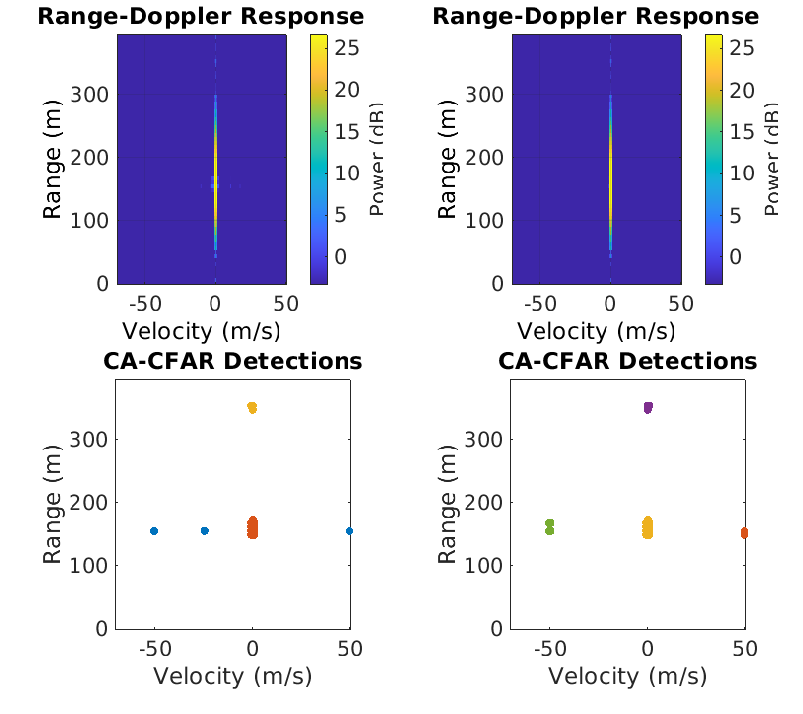

clf;
figure('Position',[1,1,900,800]);
axis fill;
tiledlayout(2,2,TileSpacing="none",Padding="tight")

    %subplot of the Doppler in the left column
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_rngdop(ceil(1)));
    imshow(X,map)
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_rngdop(ceil(frames_to_compute)));
    imshow(X,map)

    %subplot of the clustering in the right column
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_clusters(ceil(1)));
    imshow(X,map)
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_clusters(ceil(frames_to_compute)));
    imshow(X,map)

print('-r500',"generated_plots/attack_timeline",'-dsvg')
print('-r500',"generated_plots/attack_timeline",'-dpng')

## Evaluating CFAR Performance with surf plots

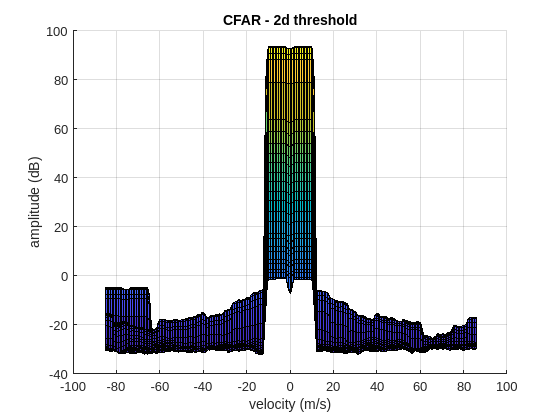

clf;
figure;

%evaluate the 2d CFAR detections for the desired frame
radar_cube = simulator.Victim.Radar_Signal_Processor.radar_cube;
[frame_resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(radar_cube);
CUT_indicies = simulator.Victim.Radar_Signal_Processor.CUT_indicies;

%configure the CFAR
release(simulator.Victim.Radar_Signal_Processor.CFARDetector2D);
simulator.Victim.Radar_Signal_Processor.CFARDetector2D.ThresholdOutputPort = true;
simulator.Victim.Radar_Signal_Processor.CFARDetector2D.OutputFormat ="CUT result";


%compute the CFAR
[detections,th] = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(abs(frame_resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);

%determine range indicies in threshold detector
ranges = rnggrid(CUT_indicies(1,:)); %y
velocities = dopgrid(CUT_indicies(2,:)); %x


dopgrid_th = linspace(min(velocities), max(velocities),max(CUT_indicies(2,:)) - min(CUT_indicies(2,:) - 1));
rnggrid_th = linspace(min(ranges), max(ranges),max(CUT_indicies(1,:)) - min(CUT_indicies(1,:) - 1));
[X,Y] = meshgrid(dopgrid_th, rnggrid_th);

%convert the thresholds to db
th = 20 * log10(th);

th_surface = griddata(velocities,ranges,th,X,Y);
surf(X, Y, th_surface);
view(0,0);
title("CFAR - 2d threshold");
xlabel("velocity (m/s)");
ylabel("range (m)");
zlabel("amplitude (dB)");

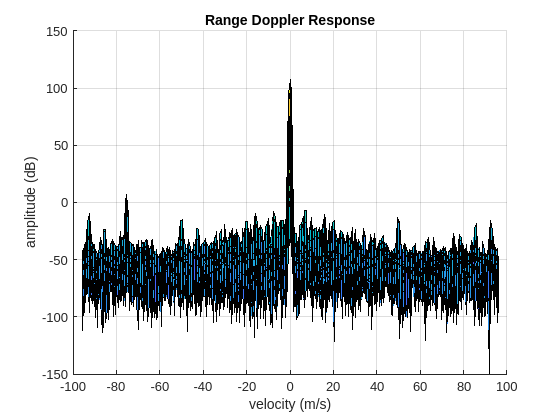


%convert the response to db
frame_resp = 20 * log10(abs(frame_resp).^2);
surf(dopgrid,rnggrid,frame_resp)
view(0,0);
title("Range Doppler Response");
xlabel("velocity (m/s)");
ylabel("range (m)");
zlabel("amplitude (dB)");

## Evaluating Range Performance

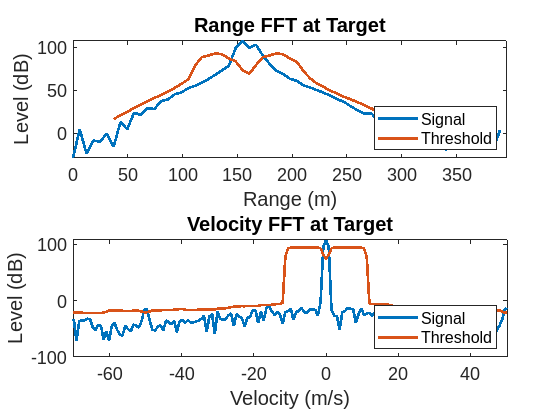

%find the maximum point
[M,I] = max(frame_resp,[],'all');
[rng_idx,vel_idx] = find(frame_resp == M);

%compute the indicies for the computed threshold
rng_idx_th = find(abs(rnggrid_th - rnggrid(rng_idx)) < 1e-4);
if isempty(rng_idx_th)
    rng_idx_th = 1;
end
vel_idx_th = find(abs(dopgrid_th - dopgrid(vel_idx)) < 1e-4);
if isempty(vel_idx_th)
    vel_idx_th = 1;
end

%plot range
rng_fft = frame_resp(:,vel_idx);
rng_th = th_surface(:,vel_idx_th);

subplot(2,1,1) 
plot(rnggrid,rng_fft,rnggrid_th,rng_th,"LineWidth",2.0)

xlim([max(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3)...
    - num_bins_zoom * simulator.Victim.Range_Res_m,...
    0), ...
    min(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3 ...
    * tgt_velocity) ...
    + num_bins_zoom * simulator.Victim.Range_Res_m,...
    simulator.Victim.Range_Max_m)])

font_size = 14;
title("Range FFT at Target","FontSize",font_size)
xlabel("Range (m)","FontSize",font_size)
ylabel("Level (dB)","FontSize",font_size)
ax = gca;
ax.FontSize = font_size;
legend('Signal','Threshold','Location','Southeast')

%plot velocity
dop_fft = frame_resp(rng_idx,:);
dop_th = th_surface(rng_idx_th,:);

subplot(2,1,2) 
plot(dopgrid,dop_fft,dopgrid_th,dop_th, "lineWidth",2.0)
legend('Signal','Threshold','Location','Southeast')
xlabel('Velocity')
ylabel('Level')
title("Velocity FFT at target")

xlim([max(tgt_velocity - num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        -1 * simulator.Victim.V_Max_m_per_s), ...
        min(tgt_velocity + num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        simulator.Victim.V_Max_m_per_s)])

font_size = 14;
title("Velocity FFT at Target","FontSize",font_size)
xlabel("Velocity (m/s)","FontSize",font_size)
ylabel("Level (dB)","FontSize",font_size)
ax = gca;
ax.FontSize = font_size;

%save the plots
% print('-r300',"generated_plots/CFAR_output",'-dsvg')
print('-r300',"generated_plots/CFAR_output",'-dpng')

Generate plot of IF signals

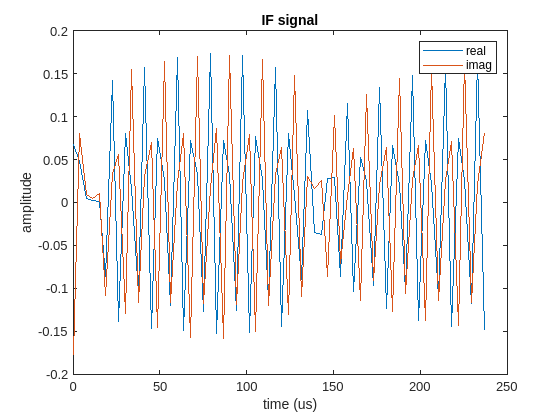

sampled_IF_sig = simulator.Victim.Radar_Signal_Processor.radar_cube(:,1);
inter_sample_period = 1/simulator.Victim.ADC_SampleRate_MSps;
times = 0:inter_sample_period:(simulator.Victim.ADC_Samples - 1) * inter_sample_period;
clf;
plot(times,real(sampled_IF_sig),times, imag(sampled_IF_sig));
legend("real","imag")
xlabel("time (us)")
ylabel("amplitude")
title("IF signal")
print('-r300',"generated_plots/if_signal",'-dsvg')
print('-r300',"generated_plots/if_signal",'-dpng')

#### Plot Range FFT

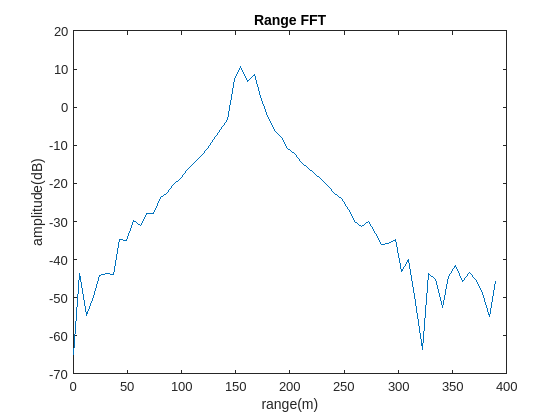

window = hann(simulator.Victim.ADC_Samples);
windowed_sig = window .* radar_cube(:,1);
range_fft = 20 * log10(abs(fft(windowed_sig)));
clf;
plot(simulator.Victim.Ranges,range_fft)
title("range FFT at target")
xlabel("range(m)")
ylabel("amplitude(dB)")
title("Range FFT")
print('-r300',"generated_plots/Range_fft",'-dsvg')
print('-r300',"generated_plots/Range_fft",'-dpng')

## Code to align the rx and the tx signal using cross correlation

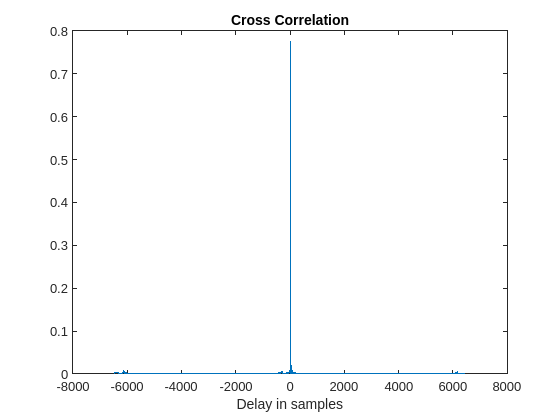

[C,lag] = xcorr(Rx_sig,Tx_sig,"normalized");
clf;
plot(lag,abs(C));
xlabel("Delay in samples")
title("Cross Correlation")

[M,I] = max(abs(C));
delay_samps = lag(I)

delay_samps = 26

delay_us = delay_samps * simulator.Victim.FMCW_sampling_period_s * 1e6

delay_us = 1.0398

%positive lag is ahead of time (decrease the offset_us term)